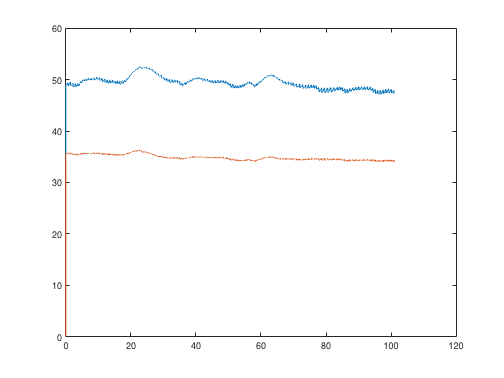


ADC_bits = 14;
V_ADC = 3.3;
Fs = 125;

R = sample(:,1)./(2^ADC_bits-1).*V_ADC;
IR = sample(:,2)./(2^ADC_bits-1).*V_ADC;
t = linspace(0,length(R)/Fs, length(R));

clf
plot(t,R)
hold on
plot(t, IR)


[ppg_sig, SpO2, ratio] = getPPGfromChannels(sample(:,1), sample(:,2));

ratio_of_ratios = 2.1657



SpO2

SpO2 = 96.1503

resp_rate =  getRespiratoryRateFreq(t, ppg_sig)*60

resp_rate = 12.3412

[sys,dias,feet] = findPPGPeaks(ppg_sig, Fs);
sortedFeatures = sortPPGPeaks(sys, dias, feet);
hr = heartRateFromPPG(sortedFeatures(:,1), sortedFeatures(:,4),Fs)

hr = 62.8914

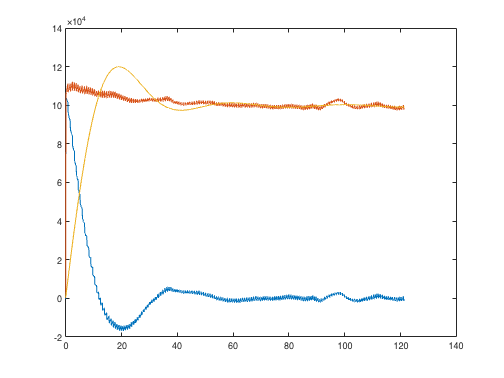

samp_freq =  mean(1./diff(t));
filt_design = designfilt('highpassiir','FilterOrder',4, ...
    'HalfPowerFrequency',0.05/samp_freq,'DesignMethod','butter');
R_ac =  filtfilt(filt_design, R);
R_dc = R-R_ac;

clf
plot(t, R_ac);
hold on
plot(t, R)
plot(t, R_dc)

R_dc = movmean(R, 500);
R_ac = R - R_dc;

IR_dc = movmean(IR, 500);
IR_ac = IR - IR_dc;

ratio = mean(R_ac)/mean(R_dc)*mean(IR_dc)/mean(IR_ac)

ratio = 1.0445

104-17.*ratio

ans = 86.2441



samp_freq =  mean(1./diff(t));
filt_design = designfilt('highpassiir','FilterOrder',4, ...
    'HalfPowerFrequency',0.5/samp_freq,'DesignMethod','butter');

R_ac = filtfilt(filt_design, R);
R_dc = R-R_ac;

IR_ac = filtfilt(filt_design,IR);
IR_dc = IR - IR_ac;

ratio = mean(R_ac)/mean(R_dc)*mean(IR_dc)/mean(IR_ac)

ratio = 0.7963

104-17.*ratio

ans = 90.4625

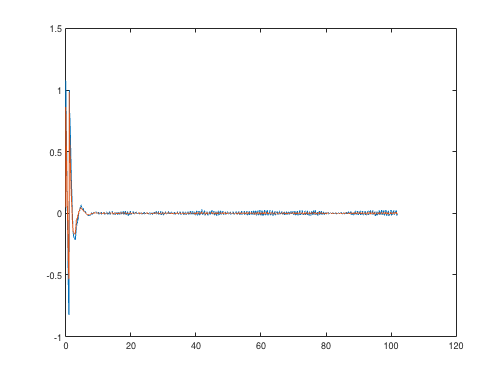


clf
plot(t, R_ac)
hold on
plot(t, IR_ac)

[~, lowerR] = envelope(R, 400, 'peak');
R_ac = R - lowerR;
[~, lowerIR] = envelope(IR, 400, 'peak');
IR_ac = IR - lowerIR;

ratio = mean(R_ac)/mean(lowerR)*mean(lowerIR)/mean(IR_ac)

ratio = 2.0765

104-17./ratio

ans = 95.8130

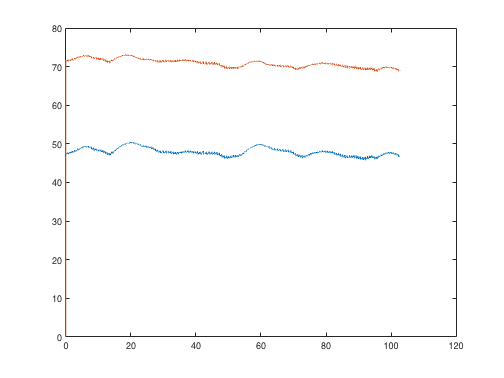


% clf
% plot(t(100:end),IR(100:end))
% hold on
% 
% plot(t(100:end), lowerIR(100:end))
clf
plot(t, R)
hold on 
plot(t, IR.*ratio)